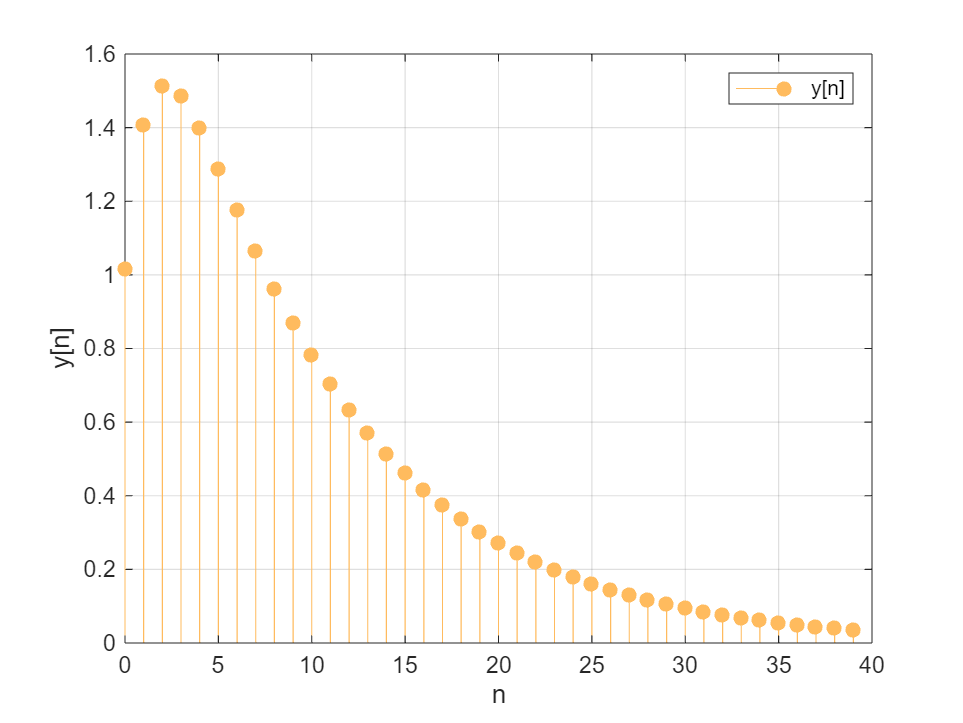

figure
 xn4 = 0:39;
 xn = 0.9.^xn4;
 hn = 0.5.^xn4;
 zn = conv([xn xn],hn);
 time = 0;
 for i = 0:1:49
    f = @()(conv([xn xn],hn));
    t_timeie2 = timeit(f);
    time = time+t_timeie2;
 end
 yn=zn(41:80);
 stem(xn4,yn,'filled','Color',[255,187,94]/255);
 grid on
 xlabel('n');
 ylabel('y[n]')
 legend('y[n]')


 fprintf('执行时间（秒）： %.6f\n', time/50);

执行时间（秒）： 0.000001


 f40c = time/50

f40c = 1.2659e-06